# Método de Bisección

El método de bisección es una variación del método de búsqueda incremental en el que el intervalo siempre se divide por la mitad. Si una función cambia de signo durante un intervalo, se evalúa el valor de la función en el punto medio. Luego se determina que la ubicación de la raíz se encuentra dentro del subintervalo donde ocurre el cambio de signo. El subintervalo se convierte entonces en el intervalo para la siguiente iteración. El proceso se repite hasta que se conoce la raíz con la precisión requerida.

En general, si *f(x) *es real y continúa en el intervalo que va desde un límite inferior (**xl**) hasta un límite superior (**xu**) y **f(xl)** y **f(xu)** tienen signos opuestos, es decir:

## 
$$f(x_{l})*f(x_{u})<0$$
 

Entonces hay al menos una raíz real entre **xl** y **xu**.

## Definición de los parámetros de entrada

El primer paso consiste en la definición de la función a solicionar:

func=@(x)-0.5.*x.^2 + 2.5.*x + 4.5; %Función de la cual se desea conocer las raices

## Métodos Gráficos

Un método simple para obtener una aproximación a la raíz de la ecuación *f (x) = 0 *consiste en graficar la función y observar dónde cruza el eje x. Este punto, que representa el valor de x para el cual *f(x) = 0*, ofrece una aproximación inicial de la raíz y permite establecer los valores iniciales de **xl** y **xu**.

Valor del límite inferior para los ejes de la gráfica

lin = -10; %Valor del límite inferior para los ejes de la gráfica

Valor del límite superior para los ejes de la gráfica

lsup = 10;%Valor del límite superior para los ejes de la gráfica

Paso o resolución para el gráfico

paso = 0.1; %Paso o resolución para el gráfico

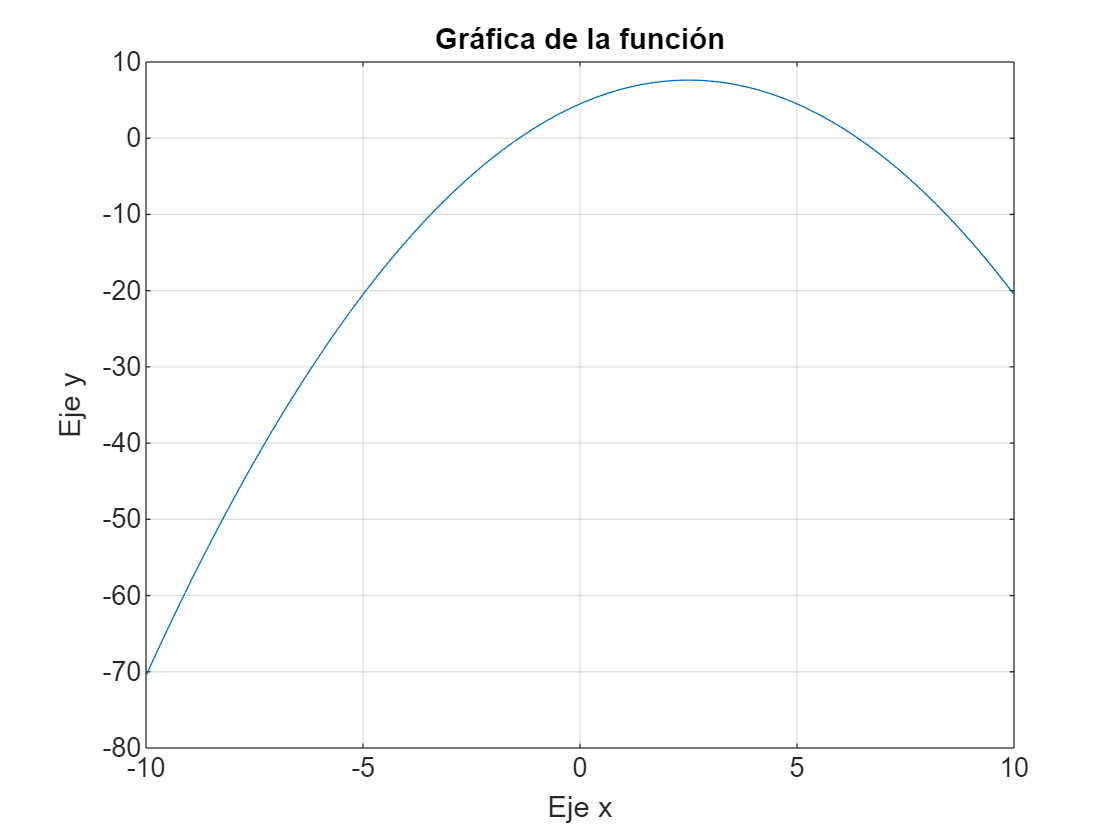

x=(lin:paso:lsup);
y = func(x);
plot(x,y);
title('Gráfica de la función') %Título de la gráfica
xlabel('Eje x') %Título del eje x de la gráfica
ylabel('Eje y') %Título del eje y de la gráfica
grid on; %Activa la cuadricula en la gráfica

Una vez definida la función de la cual se desea conocer la raíz que cumpla que *f(x) = 0*, se puede iniciar con el algoritmo del método de bisección.

### Paso 1

Se elijen los valores iniciales inferior, **x**l, y superior, **xu**, que encierren la raíz, de forma tal que la función cambie de signo en el intervalo. 

xl = -5;
xu = 0;

Una vez definidos los valores de **xl** y **xu** se verifica que

## 
$$f(x_{l})*f(x_{u})<0$$
 

test = func(xl)*func(xu);
-92.25;
if test>0
    disp1='no hay cambio de signo';
elseif test<0
    disp1='si hay cambio de signo';
end
disp1;
'si hay cambio de signo';

### Paso 2

Una aproximación de la raíz **xr** se determina mediante: 

## 
$$x_{r}=\frac{x_{l}+x_{u}}{2}$$


xr = (xl + xu)/2; %Cálculo del valor de xr
-2.5;

## Verificación gráfica de los limites xl y xu

El método de Bisección aprovecha el hecho de que una función cambia de signo en la vecindad de una raíz. A estas técnicas se les llama *métodos cerrados*, o de *intervalos*, porque se necesita de dos valores iniciales para la raíz. Como su nombre lo indica, dichos valores iniciales deben “encerrar”, o estar a ambos lados de la raíz.

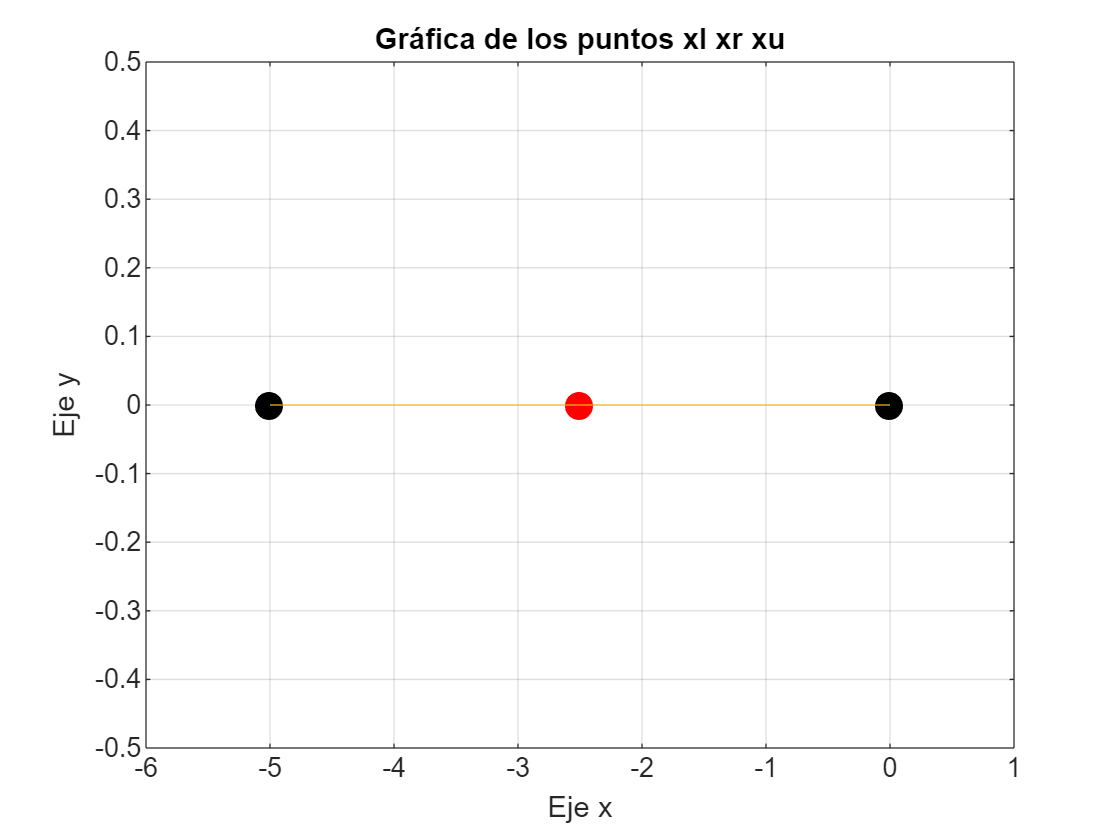

A = [xl xu];
B = [0  0];
C1 = xr;
C2 = 0;
plot(A,B,'-o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','k')
grid on
axis1 = (xl-1);
axis2 = (xu+1);
axis([axis1 axis2 -0.5 0.5])
hold on
plot(C1,C2,'-o','MarkerSize',10,'MarkerEdgeColor','r','MarkerFaceColor','r')
line(A,B)
hold off
title('Gráfica de los puntos xl xr xu') %Título de la gráfica
xlabel('Eje x') %Título del eje x de la gráfica
ylabel('Eje y') %Título del eje y de la gráfica
grid on; %Activa la cuadricula en la gráfica

### Paso 3

Se realiza la siguiente evaluación para determinar en qué subintervalo está la raíz:

## 
$$f(x_{l})*f(x_{r})$$


test2 = func(xl)*func(xr);
99.9375;

El subintervalo en el que se encuentra la raíz se selecciona de la siguiente forma:

**a)** Si *f(xl)f(xr) < 0*, entonces la raíz se encuentra dentro del subintervalo inferior o izquierdo. Por lo tanto, se establece **xu = xr** y se vuelve al paso 2.

**b)** Si *f(xl)f(xr) > 0*, entonces la raíz se encuentra dentro del subintervalo superior o derecho. Por lo tanto, se establece **xl = xr** y se vuelve al paso 2.

**c)** Si *f(xl)f(xr) = 0*, la raíz es igual a **xr**; se termina el cálculo.

if test2 < 0
xu = xr;
formatSpec = 'El nuevo valor de xu es: %8.3f';
res=fprintf(formatSpec,xu);
elseif test2 > 0
xl = xr;
formatSpec = 'El nuevo valor de xl es: %8.3f';
res=fprintf(formatSpec,xl);
elseif test2 == 0
xr = 0
formatSpec = 'El valor de xr es: %8.3f';
res=fprintf(formatSpec,xr);
end

El nuevo valor de xl es:   -2.500

## Iteración 2

Una vez que se determina el intervalo en el cual se encuentra la raíz mediante el paso 3, se vuelve al paso 2 para determinar el nuevo valor de **xr**.

xrold = xr;
xrn = (xl + xu)/2;
-1.25;

## Criterios de paro y estimaciones de errores

El método se repite para obtener una aproximación más exacta de la raíz. Se debe desarrollar un criterio objetivo para decidir cuándo debe terminar el método.

Se requiere estimar el error de forma tal que no se necesite el conocimiento previo de la raíz, esto es posible calculando el error relativo porcentual de la siguiente manera:

## 
$$\varepsilon_{a}=\left| \frac{x_{r}^{nuevo}-x_{r}^{anterior}}{x_{r}^{nuevo}} \right|*100% $$


ea = abs((xrn - xrold)/xrn) * 100;
100;

## Implementación del Método de Bisección

A continuación se muestra la solución de la función por medio del método de Bisección para determinar la raíz de una función según el criterio de paro seleccionado.

Es = 0.01; %Criterio de paro para el método de Bisección
Resultados = biseccion(func,xl,xu,Es)

Resultados = 15×8 table
    i            xl                  xu                  xr                    f(xl)                    f(xr)                 f(xl)*f(xr)                 ea         
    __    _________________    _______________    _________________    _____________________    _____________________    _____________________    ___________________

     1                 -2.5                  0                -1.25                   -4.875                  0.59375              -2.89453125                    100
     2                 -2.5              -1.25               -1.875                   -4.875               -1.9453125             9.4833984375       33.3333333333333
     3               -1.875            

function Resultados = biseccion(f,xl,xu,Es)
xr=xl; % Da un valor inicial a xr
iter=0; % variable de conteo de iteraciones
ea=100;
R=[]; %Matriz que contendrá los datos para realizar la tabla
    while (1) %Ciclo while para realizar las iteraciones
        xrold=xr; %Definición incial de xr
        xr=(xl+xu)/2; %Cálculo del xr nuevo para el método de Bisección
        iter=iter+1; %Incremento del número de iteración.
        fxlxr=f(xl)*f(xr); %Cálculo de la función evaluada en xl y xr para ver si hay cambio de signo
        if xr ~= 0 %Si xr es distinto a 0, se calcula el valor del error aproximado
        ea = abs((xr - xrold)/xr) * 100;
        end
        F=[iter xl xu xr f(xl) f(xr) fxlxr ea]; %Vector fila con los datos de cada iteración
        %F=[iter xl f(xl) xu f(xu) xr f(xr) ea]; %Vector fila con los datos de cada iteración
        R=[R;F]; %Adición del vector fila F a la tabla con los resultados del programa.
        producto = f(xl)*f(xr); %Variable para verificar el producto de f(xl) y f(xu)
        if producto < 0 %Si el producto es menor a 0, xu se sustituye por xr
        xu = xr;
        elseif producto > 0 %Si el producto es mayor a 0, xl se sustituye por xr
        xl = xr;
        else
        ea = 0; %Si el error absoluto es igual a 0, el ciclo termina (eso indica que ya se encontró el valor de xr
        %para la cual la función es 0, por tanto en ese caso xr sería la raíz). 
        end
        if ea <= Es %Si el error relativo aproximado es menor que la tolerancia, se termina el método. 
            break
        end
    end
Resultados=array2table(R,'VariableNames', {'i' 'xl' 'xu' 'xr' 'f(xl)' 'f(xr)' 'f(xl)*f(xr)' 'ea'}); %Creación de la tabla
end

Creado por Adrián Quesada Martínez 2023.